# **1. MEASURING CLIMATE CHANGE**

## **PART 1.1**

% start fresh
clc, clearvars, close all

% import data set

% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 19);

% Specify range and delimiter
opts.DataLines = [3, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Year", "Jan", "Feb", "Mar", "Apr", "May", "Jun", "Jul", "Aug", "Sep", "Oct", "Nov", "Dec", "J_D", "D_N", "DJF", "MAM", "JJA", "SON"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
tempdata1 = readtable("C:\Users\HP\Doing Economics\MATLAB\Project 1\NH.Ts+dSST.csv", opts);

% Clear temporary variables
clear opts

% Display results
tempdata1

tempdata1 = 144×19 table
    Year     Jan      Feb      Mar      Apr      May      Jun      Jul      Aug      Sep      Oct      Nov      Dec      J_D      D_N      DJF      MAM      JJA      SON 
    ____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    __

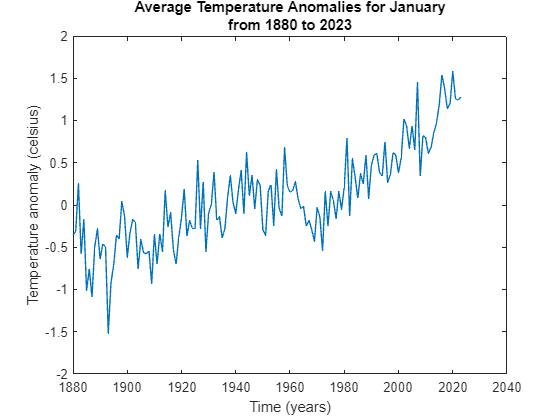

% plot average temperature anomalies for january
plot(tempdata1, 'Year', 'Jan');
title({'Average Temperature Anomalies for January', 'from 1880 to 2023'});
xlabel('Time (years)');
ylabel('Temperature anomaly (celsius)');

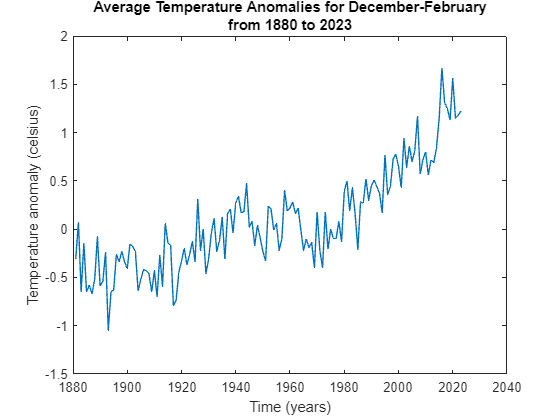

% plot average temperature anomalies for december-february
plot(tempdata1, 'Year', 'DJF');
title({'Average Temperature Anomalies for December-February', 'from 1880 to 2023'});
xlabel('Time (years)');
ylabel('Temperature anomaly (celsius)');

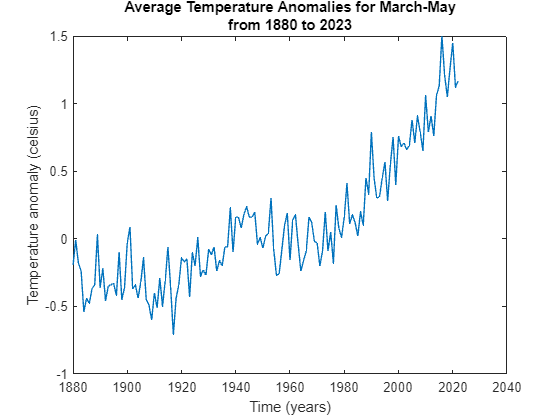

% plot average temperature anomalies for march-may
plot(tempdata1, 'Year', 'MAM');
title({'Average Temperature Anomalies for March-May', 'from 1880 to 2023'});
xlabel('Time (years)');
ylabel('Temperature anomaly (celsius)');

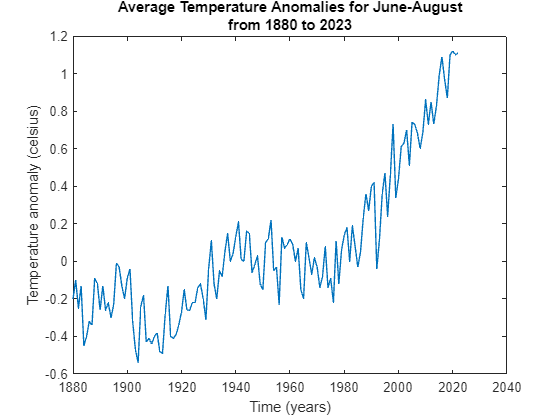

% plot average temperature anomalies for june-august
plot(tempdata1, 'Year', 'JJA');
title({'Average Temperature Anomalies for June-August', 'from 1880 to 2023'});
xlabel('Time (years)');
ylabel('Temperature anomaly (celsius)');

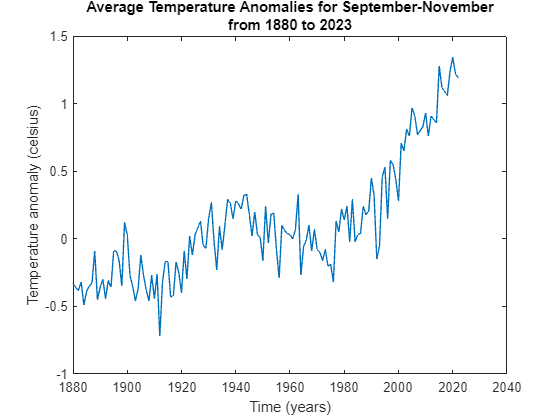

% plot average temperature anomalies for september-november
plot(tempdata1, 'Year', 'SON');
title({'Average Temperature Anomalies for September-November', 'from 1880 to 2023'});
xlabel('Time (years)');
ylabel('Temperature anomaly (celsius)');

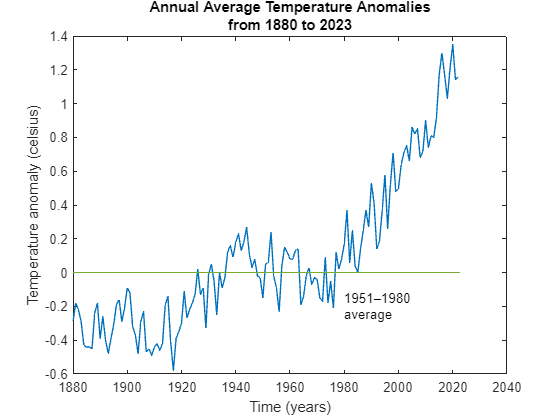

% plot annual average temperature anomalies
plot(tempdata1, 'Year', 'J_D');
hold on;
plot(table2array(tempdata1(:, 'Year')), zeros(height(tempdata1)));
text(1980, -0.2, {'1951–1980', 'average'});
title({'Annual Average Temperature Anomalies', 'from 1880 to 2023'});
xlabel('Time (years)');
ylabel('Temperature anomaly (celsius)');
hold off;

## **PART 1.2**

% get ranges of 0.05
ranges = -0.3:0.05:1.05;

% ensure value is exactly zero and not just very small
ranges(7) = 0;

% get temperatures and their frequencies of JJA in 1951-1980
temp51_80_1 = table2array(tempdata1(1951-1879:1980-1879, ["Jun", "Jul", "Aug"]));
freq51_80 = histcounts(temp51_80_1, ranges);

% add zero to ensure both arrays have the same number of elements
freq51_80(end + 1) = 0;
disp(table(ranges.', freq51_80.', 'VariableNames', {'range of temperature anomaly', 'frequency'}));

    range of temperature anomaly    frequency
    ____________________________    _________

                -0.3                    2    
               -0.25                    7    
                -0.2                    3    
               -0.15                   12    
                -0.1                   12    
               -0.05                    6    
                   0                   13    
                0.05                   14    
                 0.1                   10    
                0.15                    7    
                 0.2                    4    
                0.25                    0    
                 0.3                    0    
                0.35                    0    
                 0.4                    0    
                0.45                    0    
                 0.5                    0    
                0.55                    0    
           

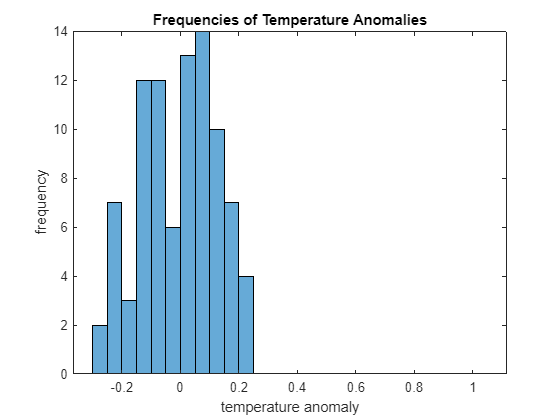

% plot histogram
hist51_80 = histogram('BinEdges', ranges, 'BinCounts', freq51_80(1:end - 1));
title('Frequencies of Temperature Anomalies');
xlabel('temperature anomaly');
ylabel('frequency');

% get temperatures and their frequencies of JJA in 1981-2010
temp81_10_1 = table2array(tempdata1(1981-1879:2010-1879, ["Jun", "Jul", "Aug"]));
freq81_10 = histcounts(temp81_10_1, ranges);

% add zero to ensure both arrays have the same number of elements
freq81_10(end + 1) = 0;
disp(table(ranges.', freq81_10.', 'VariableNames', {'range of temperature anomaly', 'frequency'}));

    range of temperature anomaly    frequency
    ____________________________    _________

                -0.3                    0    
               -0.25                    0    
                -0.2                    0    
               -0.15                    1    
                -0.1                    3    
               -0.05                    2    
                   0                    6    
                0.05                    4    
                 0.1                    3    
                0.15                    3    
                 0.2                    5    
                0.25                    7    
                 0.3                    7    
                0.35                    1    
                 0.4                    8    
                0.45                    6    
                 0.5                    5    
                0.55                    4    
           

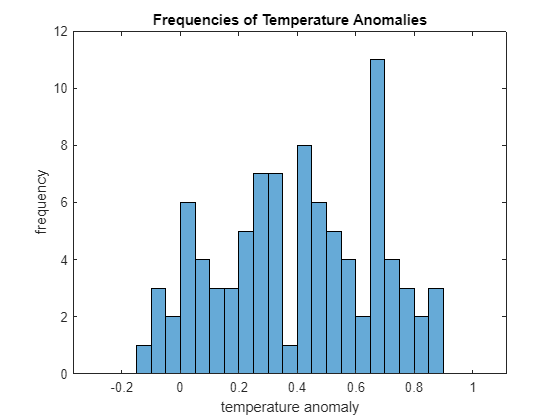

% plot histogram
hist81_10 = histogram('BinEdges', ranges, 'BinCounts', freq81_10(1:end - 1));
title('Frequencies of Temperature Anomalies');
xlabel('temperature anomaly');
ylabel('frequency');

% get temperatures of all months in 1951-1980 and their required deciles
temp51_80_2 = table2array(tempdata1(1951-1879:1980-1879, 2:13));
deciles = prctile(temp51_80_2, [30 70], 'all');

% get temperatures of all months in 1981-2010
temp81_10_2 = table2array(tempdata1(1981-1879:2010-1879, 2:13));

% find percentages of cold and hot observations in 1981-2010
cold = mean(temp81_10_2 < deciles(1), 'all') * 100;
hot = mean(temp81_10_2 > deciles(2), 'all') * 100;

% print the results
fprintf('3rd decile: \t\t%0.1f\n7th decile: \t\t%0.1f\ncold observations: \t%0.2f%%\nhot observations: \t%0.2f%%', deciles(1), deciles(2), cold, hot);

3rd decile: 		-0.1
7th decile: 		0.1
cold observations: 	1.94%
hot observations: 	84.72%

periods = ["DJF" "MAM" "JJA" "SON"];

% get temperatures needed to calculate means and variances
temp21_50 = table2array(tempdata1(1921-1879:1950-1879, 16:19));
temp51_80_3 = table2array(tempdata1(1951-1879:1980-1879, 16:19));
temp81_10_3 = table2array(tempdata1(1981-1879:2010-1879, 16:19));

% calculate mean and variance for 1921-1950
mean21_50 = mean(temp21_50);
var21_50 = var(temp21_50);

% calculate mean and variance for 1951-1980
mean51_80 = mean(temp51_80_3);
var51_80 = var(temp51_80_3);

% calculate mean and variance for 1981-2010
mean81_10 = mean(temp81_10_3);
var81_10 = var(temp81_10_3);

% organize and print means and variances
mean_var = table(periods.', mean21_50.', var21_50.', mean51_80.', var51_80.', mean81_10.', var81_10.', 'VariableNames', {'periods', '1921-1950 means', '1921-1950 variances', '1951-1980 means', '1951-1980 variances', '1981-2010 means', '1981-2010 variances'});
disp(mean_var);

    periods    1921-1950 means    1921-1950 variances    1951-1980 means    1951-1980 variances    1981-2010 means    1981-2010 variances
    _______    _______________    ___________________    _______________    ___________________    _______________    ___________________

     "DJF"        -0.034667            0.056033             -0.0023333           0.050219              0.52467             0.079226      
     "MAM"        -0.047667            0.030536             0.00033333           0.025134                0.509             0.075602      
     "JJA"           -0.056            0.020177            -0.00033333            0.01461              0.40067             0.067917      
     "SON"         0.076667            0.028299            -0.00033333 

## **PART 1.3**

% import data set

% Set up the Import Options and import the data
opts2 = spreadsheetImportOptions("NumVariables", 5);

% Specify sheet and range
opts2.Sheet = "Sheet1";
opts2.DataRange = "A2:E714";

% Specify column names and types
opts2.VariableNames = ["Year", "Month", "MonthlyAverage", "Interpolated", "Trend"];
opts2.VariableTypes = ["double", "double", "double", "double", "double"];

% Import the data
tempdata2 = readtable("C:\Users\HP\Doing Economics\MATLAB\Project 1\doing-economics-datafile-working-in-excel-project-1.xlsx", opts2, "UseExcel", false);

% Clear temporary variables
clear opts2

% Display results
tempdata2

tempdata2 = 713×5 table
    Year    Month    MonthlyAverage    Interpolated    Trend 
    ____    _____    ______________    ____________    ______

    1958      3          315.71           315.71       314.62
    1958      4          317.45           317.45       315.29
    1958      5           317.5            317.5       314.71
    1958      6          -99.99            317.1       314.85
    1958      7          315.86           315.86       314.98
    1958      8          314.93           314.93       315.94
    1958      9           313.2            313.2       315.91
    1958     10          -99.99           312.66       315.61
    1958     11          313.33           313.33       315.31
    1958     12          314.67           314.67       315.61
    1959      1          315.62           315.62        315.7

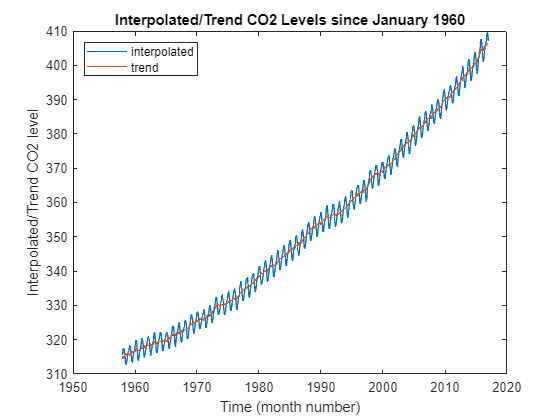

% get and plot interpolated and trend data
interpolated = tempdata2.Interpolated;
trend = tempdata2.Trend;
plot(linspace(1958, 2017, length(interpolated)), interpolated);
hold on;
plot(linspace(1958, 2017, length(trend)), trend);
title('Interpolated/Trend CO2 Levels since January 1960');
xlabel('Time (month number)');
ylabel('Interpolated/Trend CO2 level');
hold off;
legend('interpolated', 'trend', 'Location', 'northwest');

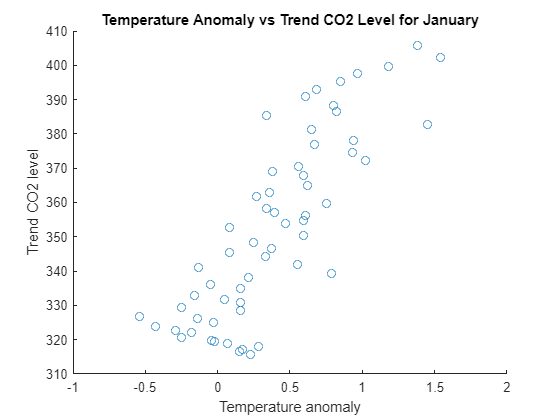

% get temperature anomalies
temp_jan = table2array(tempdata1(1959-1879:2017-1879, 'Jan'));
temp_may = table2array(tempdata1(1958-1879:2017-1879, 'May'));
temp_sep = table2array(tempdata1(1958-1879:2016-1879, 'Sep'));

% get CO2 trend levels
co2_jan = table2array(tempdata2(tempdata2.Month == 1, 'Trend'));
co2_may = table2array(tempdata2(tempdata2.Month == 5, 'Trend'));
co2_sep = table2array(tempdata2(tempdata2.Month == 9, 'Trend'));

% plot temperature anomalies against CO2 trend levels for january
scatter(temp_jan, co2_jan);
title('Temperature Anomaly vs Trend CO2 Level for January');
xlabel('Temperature anomaly');
ylabel('Trend CO2 level');

% get correlation matrix for january
cm_jan = corrcoef(temp_jan, co2_jan);

% get and print correlation coefficient for january
corr_jan = cm_jan(1, 2);
fprintf('correlation coefficient for january: %f', corr_jan);

correlation coefficient for january: 0.831030

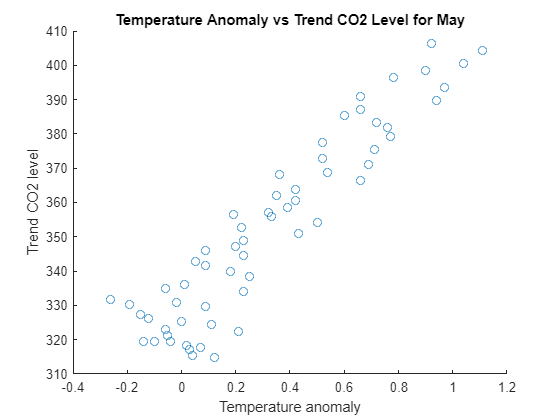

% plot temperature anomalies against CO2 trend levels for may
scatter(temp_may, co2_may);
title('Temperature Anomaly vs Trend CO2 Level for May');
xlabel('Temperature anomaly');
ylabel('Trend CO2 level');

% get correlation matrix for may
cm_may = corrcoef(temp_may, co2_may);

% get and print correlation coefficient for may
corr_may = cm_may(1, 2);
fprintf('correlation coefficient for may: %f', corr_may);

correlation coefficient for may: 0.932879

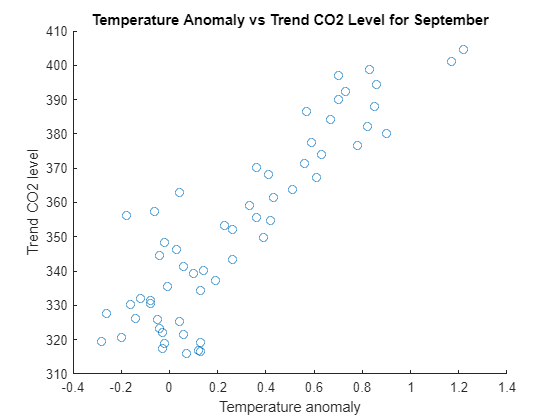

% plot temperature anomalies against CO2 trend levels for september
scatter(temp_sep, co2_sep);
title('Temperature Anomaly vs Trend CO2 Level for September');
xlabel('Temperature anomaly');
ylabel('Trend CO2 level');

% get correlation matrix for may
cm_sep = corrcoef(temp_sep, co2_sep);

% get and print correlation coefficient for september
corr_sep = cm_sep(1, 2);
fprintf('correlation coefficient for september: %f', corr_sep);

correlation coefficient for september: 0.886113